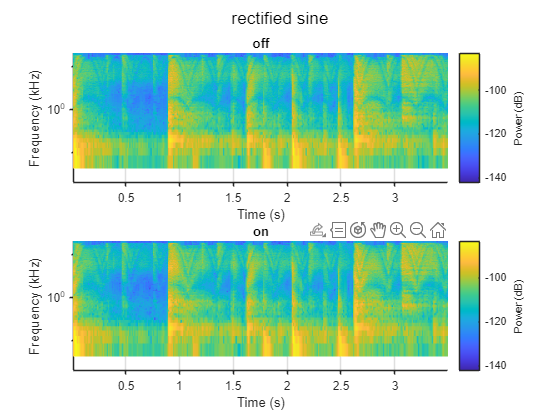

filename = 'sample_100_sine_off.mp3';
filename2 = 'sample_100_sine_on.mp3';
[y,fs] = audioread(filename);
[y2,fs] = audioread(filename2);

figure(1);
subplot(2,1,1);
spectrogram(y,1024,512,[],fs,'power','yaxis');
ax = gca; %get current axes
ax.YScale = 'log';
ax.YLim = [0.02 20];
title('off');

subplot(2,1,2);
spectrogram(y2,1024,512,[],fs,'power','yaxis');
ax = gca; %get current axes
ax.YScale = 'log';
ax.YLim = [0.02 20];
title('on')
sgtitle('rectified sine');